clear
load data3.mat
n=length(data.CzasLokalnyUTC0100);
data.CzasLokalnyUTC0100(1:4)

ans = 4×1 datetime array
   2024-05-20 23:00:00
   2024-05-20 23:01:00
   2024-05-20 23:02:00
   2024-05-20 23:02:00


data.CzasLokalnyUTC0100(n-3:n)

ans = 4×1 datetime array
   2024-05-23 01:57:00
   2024-05-23 01:58:00
   2024-05-23 01:59:00
   2024-05-24 02:00:00


T=60; %[s]
fs=1/T; %[Hz]
t=T*(0:n-1);
Kompresor1=data.StanKompresor;
StanCzujnikaZamkniecia=data.StanCzujnikZamkniciaDrzwi;
TemperaturaOtoczenia=0.1*data.TemperaturaOtoczenia;
Wlot=0.1*data.TemperaturaSterujca;
X=Wlot;
compressor=data.StanKompresor;
[x,nan_indices]  = GetRidOfNans(X);


cycle_locs=compressorCycles(compressor);
% plot(x);hold on
% plot(cycle_locs,(x(cycle_locs)),'o');hold off
% title('Detection of peaks on Sonda temperature')
% xlabel('Samples')
% ylabel('Temperature [C]')
features = FeatureExtract(x,cycle_locs);
f1=zeros(1,length(cycle_locs)-1);
for i=1:length(cycle_locs)-1
    f1(i)=cycle_locs(i+1)-cycle_locs(i);
end

cycle_locs=cycle_locs(2:end);
% figure 
% subplot(311)
% plot(cycle_locs,f1,'o-')
% subplot(312)
% plot(cycle_locs,features(3,:),'o-')
% subplot(313)
% plot(cycle_locs,features(1,:)-features(2,:),'o-')

fridge_air_temp_p2p=features(1,:)-features(2,:);
indexContainer=cell(1);
indexContainer{1}=[];
set=1;
figure
TF = isoutlier(fridge_air_temp_p2p);
TF2 = isoutlier(f1);
% plot(cycle_locs(1),(x(cycle_locs(1))),'Marker','o',"Color",'green');hold on
for i=2:length(features)
    
    if (TF(i)==0 && TF2(i)==0)
        % plot(cycle_locs(i-1):cycle_locs(i),...
        %     (x(cycle_locs(i-1):cycle_locs(i))),"Color",'blue');
        % plot(cycle_locs(i),(x(cycle_locs(i))),'Marker','o',"Color",'green');
        indexContainer{set}=[indexContainer{set},cycle_locs(i-1):cycle_locs(i)];
    else
        if TF(i-1)==0
            set=set+1;
            indexContainer{set}=[];
        end
    end
end
% % plot(locs,(X_filtered(4,locs)),'Marker','o',"Color",'green');
% hold off
% title('Detection of peaks on evaporator temperature')
% xlabel('Samples')
% ylabel('Temperature [C]')

## Setting proper index container Convergence Analysis:

--- Segment 1 ---
Measured ON-time   = 0.1 h
Predicted ON-time  = 0.1 h
Difference         = -5.0 s (-2.6%)

--- Segment 2 ---
Measured ON-time   = 0.0 h
Predicted ON-time  = 0.0 h
Difference         = +3.0 s (3.1%)

--- Segment 3 ---
Measured ON-time   = 0.0 h
Predicted ON-time  = 0.0 h
Difference         = -4.0 s (-4.7%)

--- Segment 4 ---
Measured ON-time   = 0.1 h
Predicted ON-time  = 0.1 h
Difference         = -6.0 s (-2.7%)

--- Segment 5 ---
Measured ON-time   = 0.1 h
Predicted ON-time  = 0.1 h
Difference         = -3.0 s (-1.3%)

--- Segment 6 ---
Measured ON-time   = 0.0 h
Predicted ON-time  = 0.0 h
Difference         = +2.0 s (3.0%)

--- Segment 7 ---
Measured ON-time   = 0.1 h
Predicted ON-time  = 0.0 h
Difference         = -9.0 s (-4.8%)

--- Segment 8 ---
Measured ON-time   = 0.0 h
Predicted ON-time  = 0.0 h
Difference         = -3.0 s (-8.1%)

--- Segment 9 ---
Measured ON-time   = 0.0 h
Predicted ON-time  = 0.0 h
Difference         = -3.0 s (-3.6%)

--- Segment 1 ---
Mea

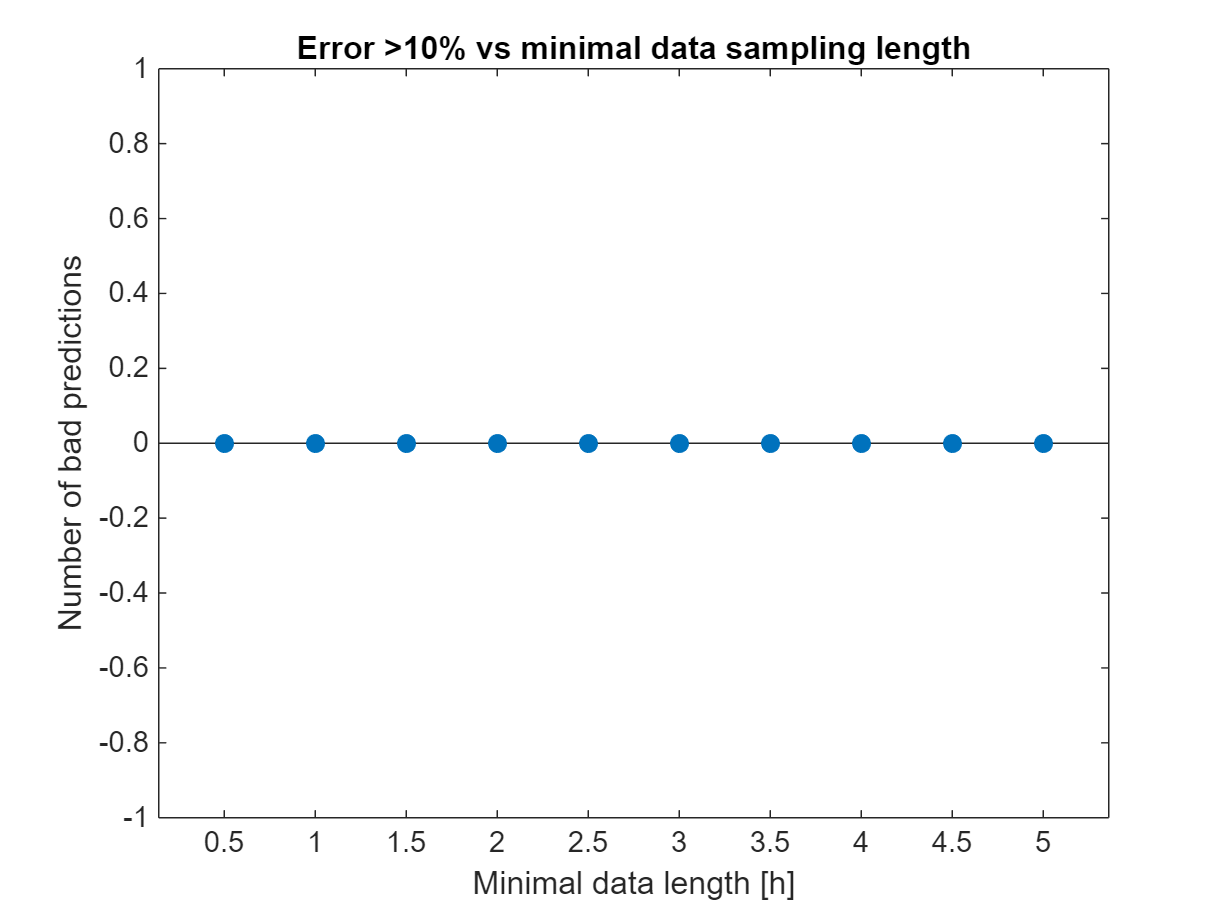

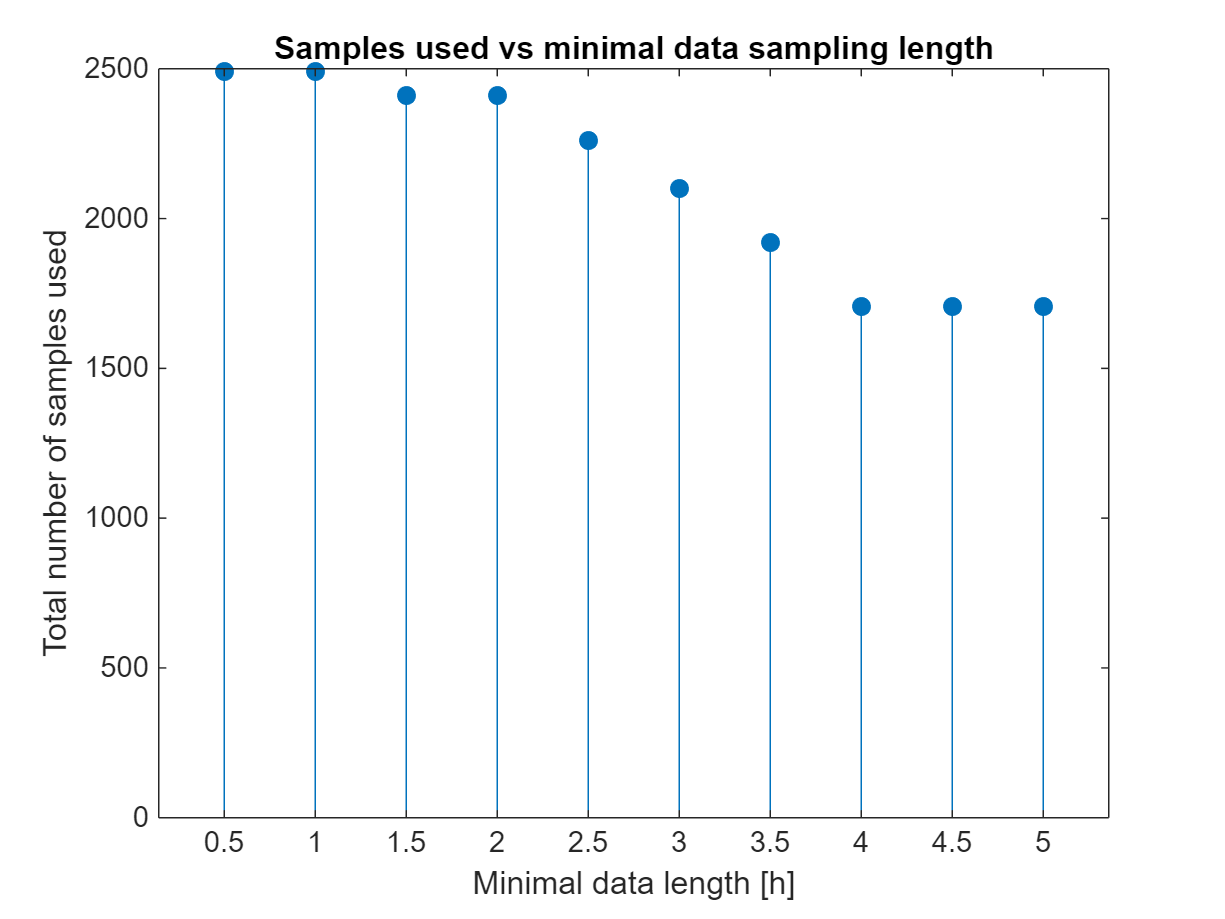

TimeScale=0.5;
runs=10;
evaluateDataLengthEffects(indexContainer,...
    t, x, compressor, fs,runs, TimeScale,...
    'PeakOffset', -2, ...
    'ValleyOffset', -1);

### Setting proper index container from Minimal data length convergence analysis:

set=1;
usableDataIndex_length = 0;
clear usableDataIndex
for i = 1:length(indexContainer)
    if length(indexContainer{i})>60*60*1*fs
        usableDataIndex{set}=indexContainer{i};
        usableDataIndex_length = usableDataIndex_length + length(indexContainer{i});
        set=set+1;
    end
end

## Peak-Valleys detection based compressor prediction:

results = analyzeCompressorSegments( ...
    t, x, compressor, usableDataIndex, ...
    'MinPeakProminence', 0.8, ...
    'MinPeakDistance', 0.17, ...
    'PlotResults', false, ...
   'PeakOffset', -2, ...
   'ValleyOffset', -1);

--- Segment 1 ---
Measured ON-time   = 0.1 h
Predicted ON-time  = 0.1 h
Difference         = -5.0 s (-2.6%)

--- Segment 2 ---
Measured ON-time   = 0.0 h
Predicted ON-time  = 0.0 h
Difference         = +3.0 s (3.1%)

--- Segment 3 ---
Measured ON-time   = 0.0 h
Predicted ON-time  = 0.0 h
Difference         = -4.0 s (-4.7%)

--- Segment 4 ---
Measured ON-time   = 0.1 h
Predicted ON-time  = 0.1 h
Difference         = -6.0 s (-2.7%)

--- Segment 5 ---
Measured ON-time   = 0.1 h
Predicted ON-time  = 0.1 h
Difference         = -3.0 s (-1.3%)

--- Segment 6 ---
Measured ON-time   = 0.0 h
Predicted ON-time  = 0.0 h
Difference         = +2.0 s (3.0%)

--- Segment 7 ---
Measured ON-time   = 0.1 h
Predicted ON-time  = 0.0 h
Difference         = -9.0 s (-4.8%)

--- Segment 8 ---
Measured ON-time   = 0.0 h
Predicted ON-time  = 0.0 h
Difference         = -3.0 s (-8.1%)

--- Segment 9 ---
Measured ON-time   = 0.0 h
Predicted ON-time  = 0.0 h
Difference         = -3.0 s (-3.6%)



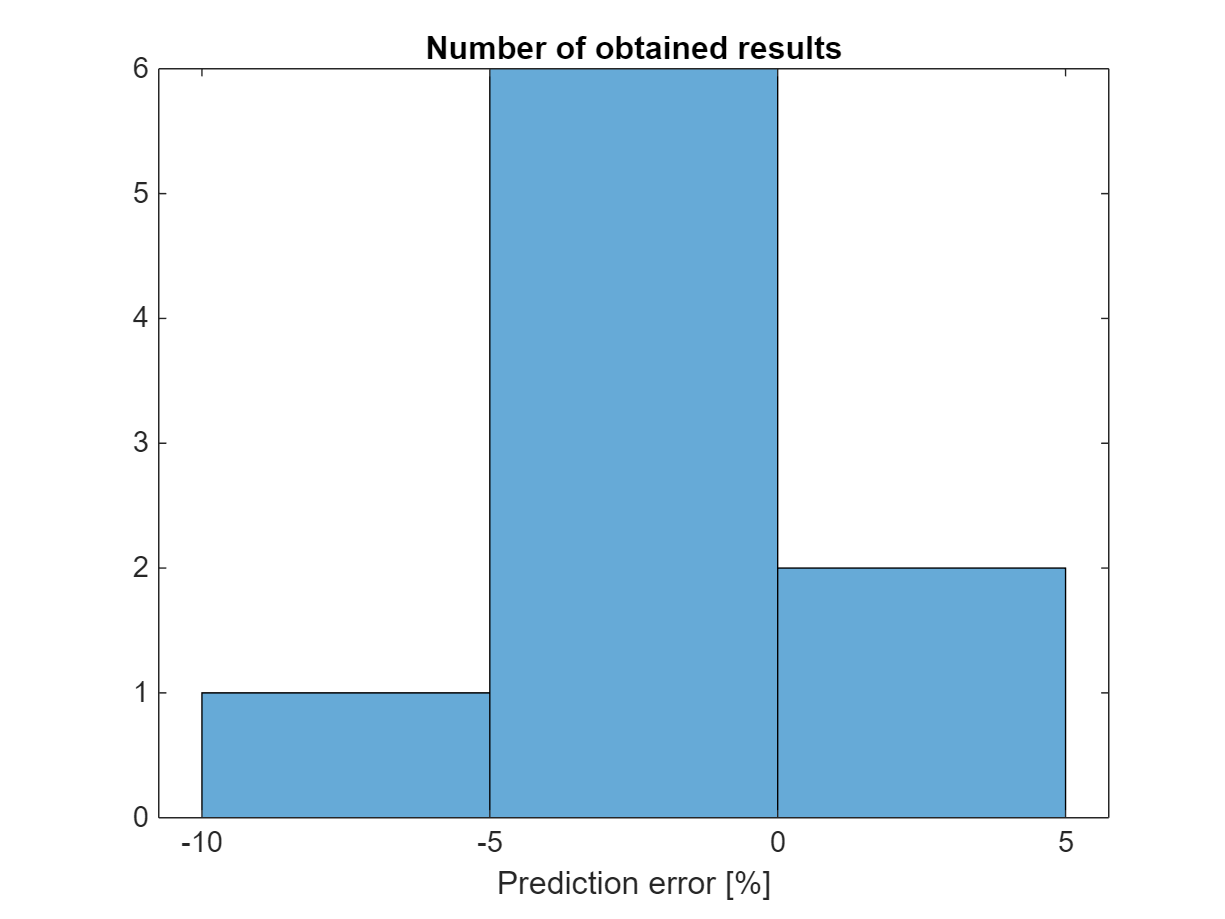

pctErrorVector=nan(1,length(results));
for i=1:length(results)
    pctErrorVector(i)=results(i).stats.pctError;
end
histogram(pctErrorVector)
xlabel('Prediction error [%]')
title('Number of obtained results')

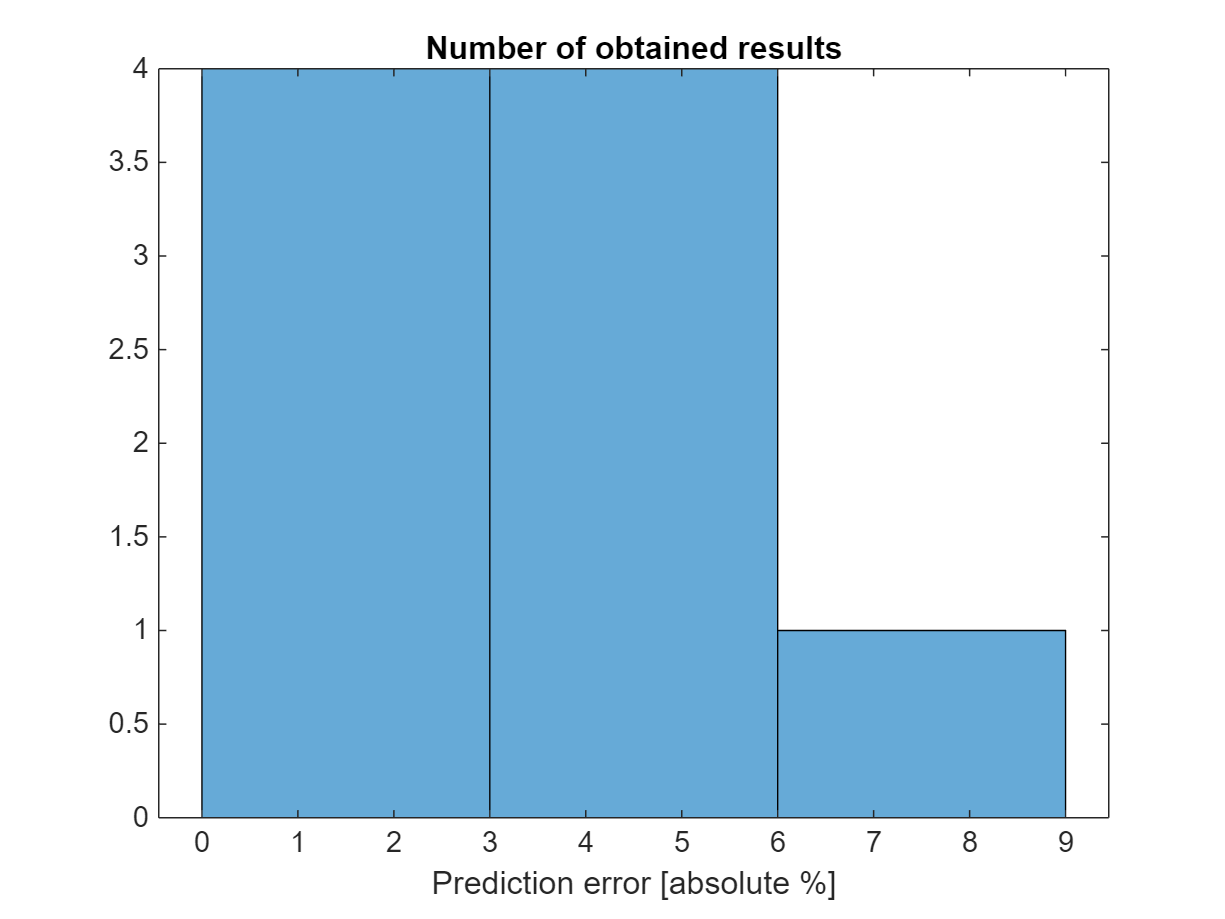

histogram(abs(pctErrorVector))
xlabel('Prediction error [absolute %]')
title('Number of obtained results')

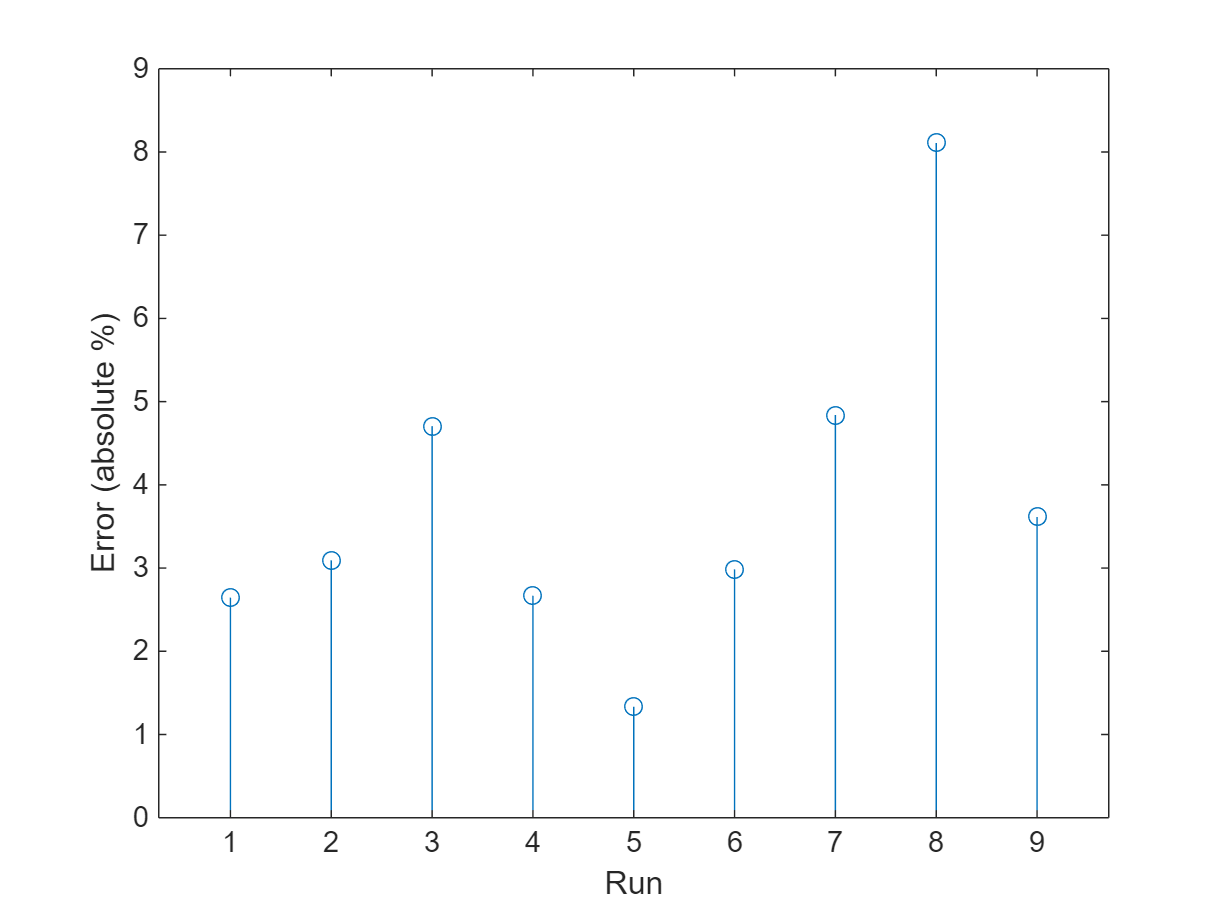

stem(abs(pctErrorVector))
xlabel('Run')
ylabel('Error (absolute %)')

fprintf('\n=== Data Quality / Error Summary ===\n');


=== Data Quality / Error Summary ===


fprintf('Mean Absolute Percentage Error (MAPE):   %.4f\n',  mean(abs(pctErrorVector)));

Mean Absolute Percentage Error (MAPE):   3.7767


fprintf('Length of usableDataIndex array [h]:        %d\n',     usableDataIndex_length/(60*60*fs));

Length of usableDataIndex array [h]:        4.153333e+01
